# Procesamiento Digital de la Señal 2020/2021.

## Práctica 1. Introducción a Señales y Sistemas en Tiempo Discreto.

Objetivo: El objetivo de esta práctica es asentar conceptos básicos sobre las señales y los sistemas en tiempo discreto. En primer lugar se presentarán algunos ejemplos de señales sencillas, con las que se podrán comprobar cómo se realizan las propiedades básicas de escalado y desplazamiento de señales.

Después se usarán estas señales para probar la respuesta de distintos sistemas, tratando de determinar si poseen o no las propiedades de invarianza en el tiempo, linealidad, y/o causalidad. También se analizarán ejemplos de interconexión de sistemas.

### 1. Introducción a las Señales

#### 1.1. Señales Elementales

En el listado 1 se muestra el código de un script de MATLAB®, usado para representar de manera gráfica diferentes señales en tiempo discreto. Para ejecutar dicho código, basta escribir el nombre del script en la consola de MATLAB®, seguido del retorno de carro.

%ap11 Representación gráfica de señales en tiempo discreto

% Inicio de figuras y memoria
close all;clear;
% Eje de tiempos discreto
n=-10:10;

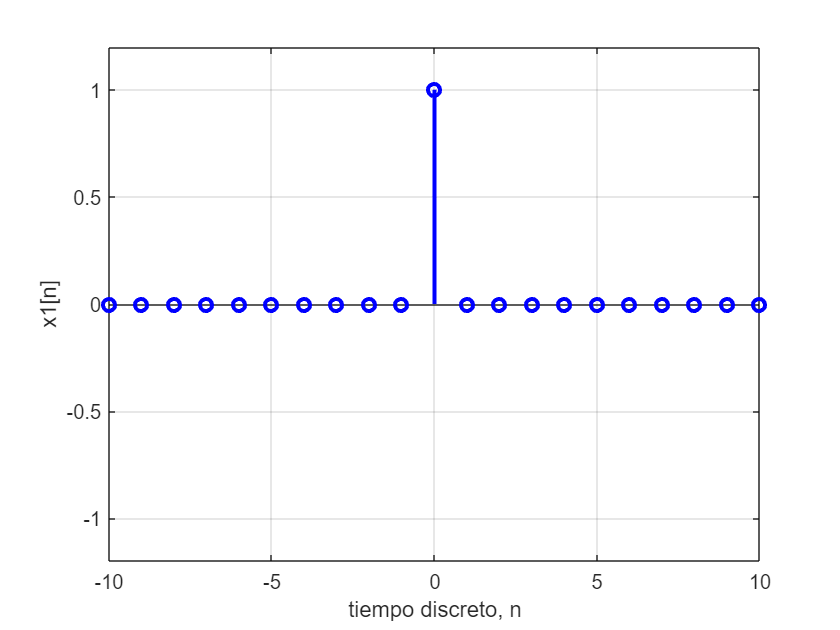

% Delta discreta
x1=delta(n);
figure;
stem(n,x1,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('x1[n]');
axis([-10 10 -1.2 1.2]);
grid

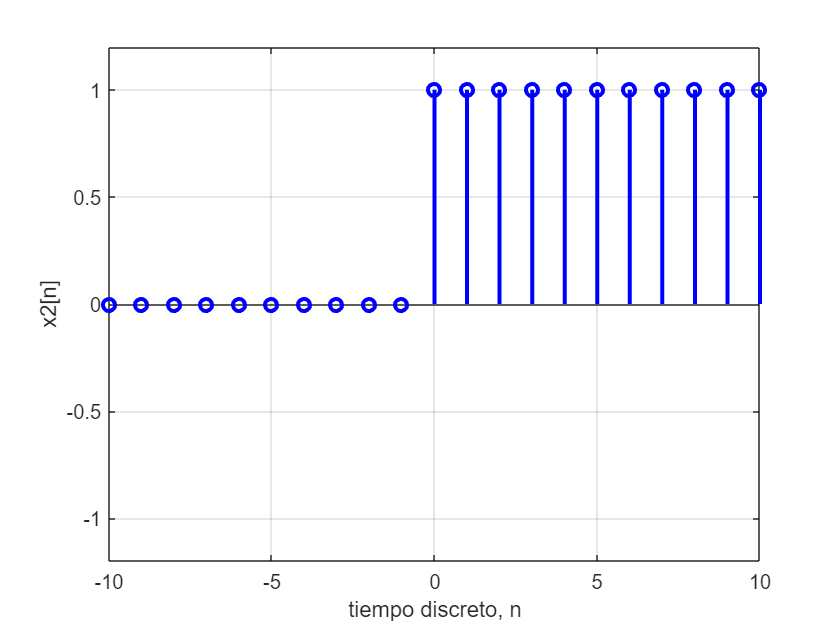

% Señal escalón unitario u(n)
x2=escalon(n);
figure;
stem(n,x2,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('x2[n]');
axis([-10 10 -1.2 1.2]);
grid

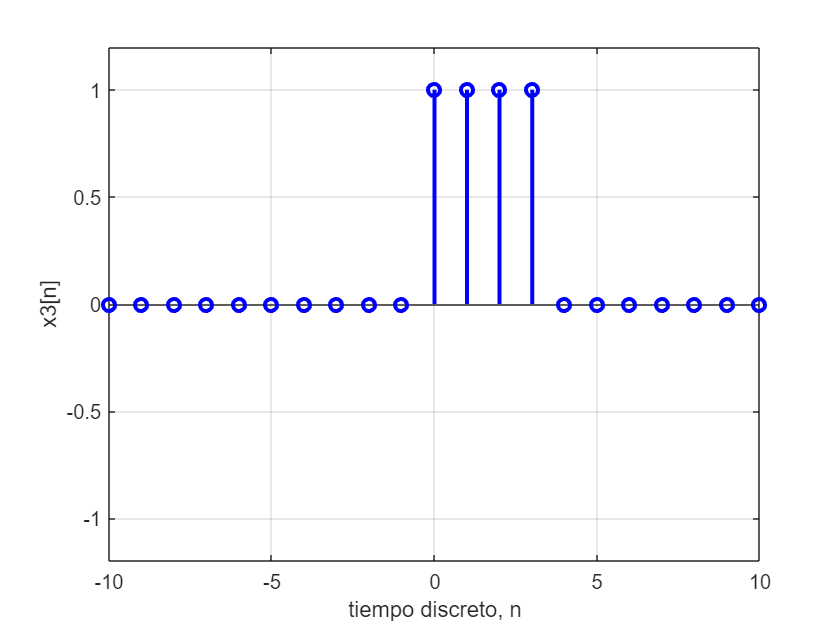

% Señal tipo pulso anchura w muestras (w>0)
w=4;
x3=pulsow(n,w);
figure;stem(n,x3,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('x3[n]');
axis([-10 10 -1.2 1.2]);
grid

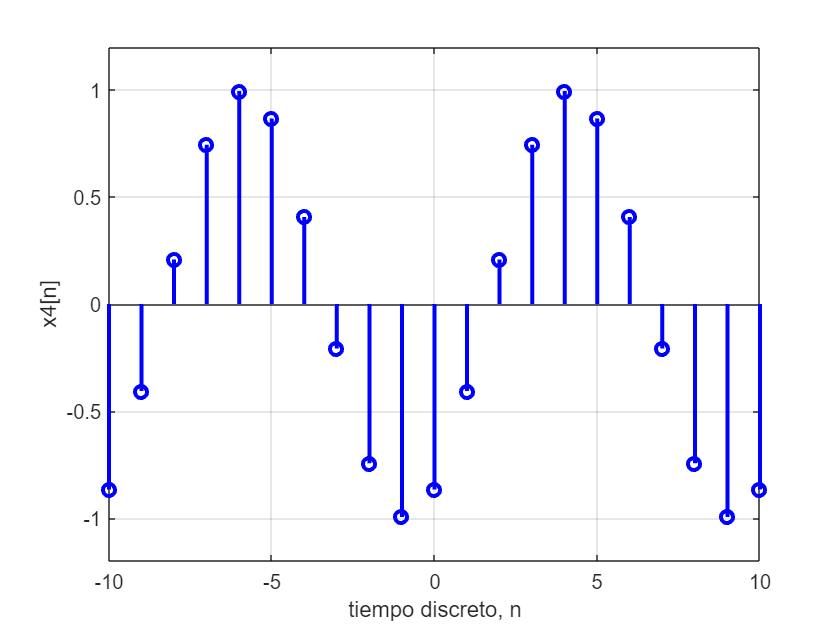

% Ejemplo de señal sinusoidal discreta
x4=sin(pi*n/5-pi/3);
figure;
stem(n,x4,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('x4[n]');
axis([-10 10 -1.2 1.2]);
grid

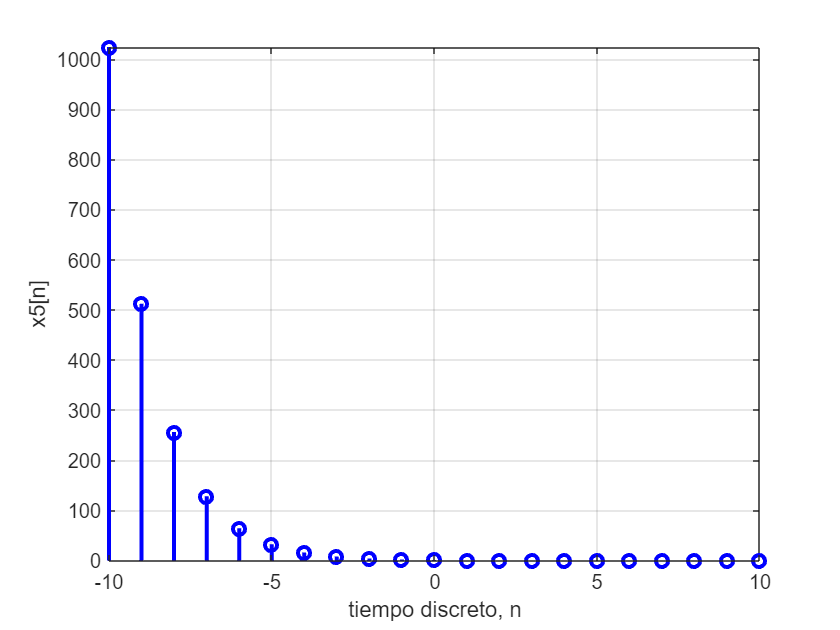

% Señal tipo exponencial
a=1/2;
x5=a.^n;
figure;
stem(n,x5,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('x5[n]');
axis([-10 10 -1.2 2^10]);
grid

Los dos primeros comandos de la línea 4 sirven para cerrar todas las figuras que hubiera abiertas y borrar de la memoria las variables usadas hasta ahora. El vector definido en la línea 6 servirá como eje de tiempo discreto para las señales que vayamos a calcular y representar.

(a) ¿Es posible representar la señal x1[n] usando la señal escalon? Modifica el código del script con el objeto de representar en una nueva figura esta posibilidad, confirmando tu respuesta con lo observado en la representación gráfica.

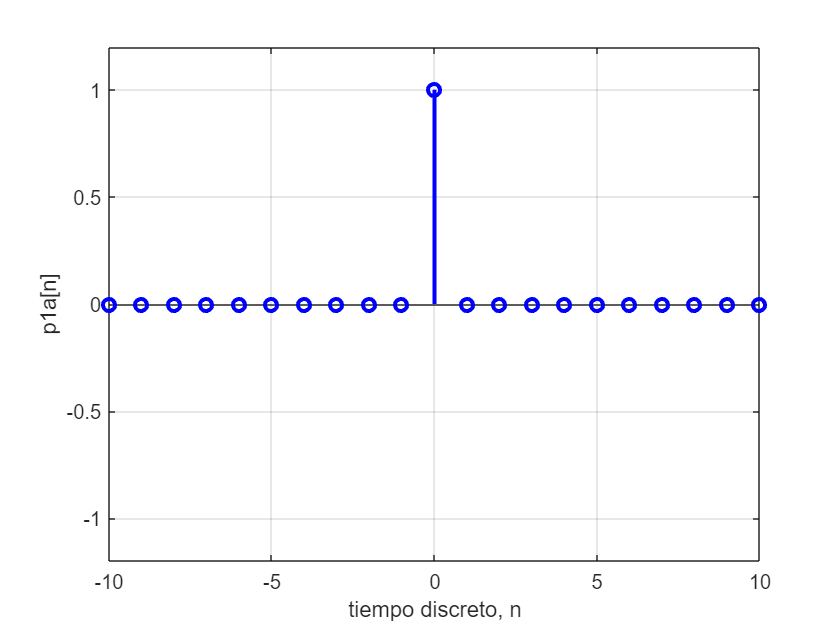

% Señal escalón unitario u(n)
p1a =escalon(n)-escalon(n-1);
figure;
stem(n,p1a,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('p1a[n]');
axis([-10 10 -1.2 1.2]);
grid

(b) A partir de las líneas de código determine la frecuencia angular w0 y el periodo N0 de la señal discreta x4[n] y comprueba que los valores coinciden con los que se deducen de la representación gráfica.

- frecuencia angular: x4=sin(pi·n/5-pi/3) => x4=sin(w0·n + Phi) => w0 = pi/5

- periodo: x4[n] = x4[n+N0] => sin(pi·n/5-pi/3)=sin(pi·(n+N0)/5-pi/3) => pi·n/5 + pi·N0/5 - pi·n/5 = 2·pi => N0 = 10

(c) Modifica el código del script con el objeto de representar en una nueva figura la señal sinusoidal discreta xS[n] = sen(n/2−pi/3). ¿Es esta señal periódica? Confirma tu respuesta con lo observado en la representación gráfica. 

- periodo: xS[n]=xS[n+N0] => (n/2+N0)-n/2 = k·2·pi => n+2N0-n = 4·k·pi =>  N0 = 2·k·pi => no periódica

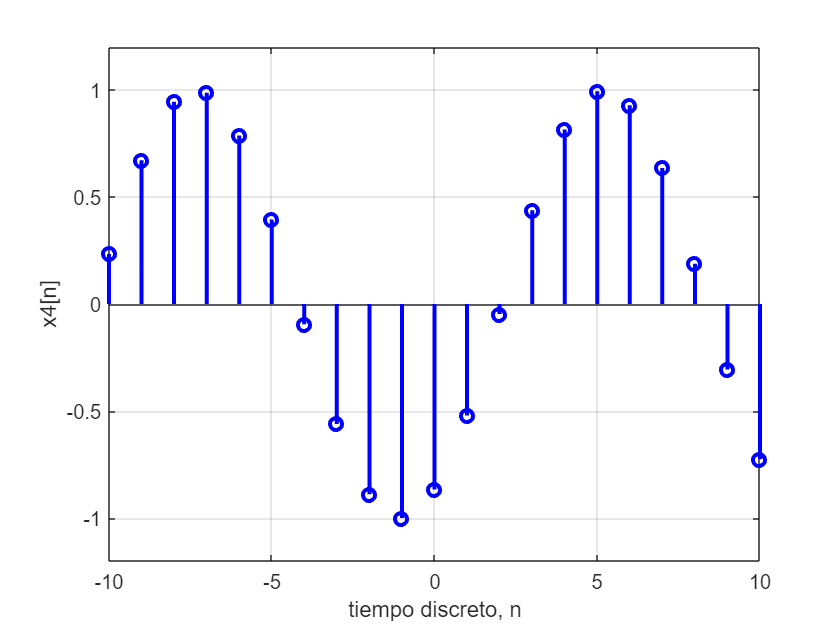

% Ejemplo de señal sinusoidal discreta
xS=sin(n/2-pi/3);
figure;
stem(n,xS,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('x4[n]');
axis([-10 10 -1.2 1.2]);
grid

(d) Modifica el código del script para que la señal x5[n] se anule para n < 0, y representa el resultado en una nueva figura. ¿Cuál es la expresión de la nueva señal obtenida?

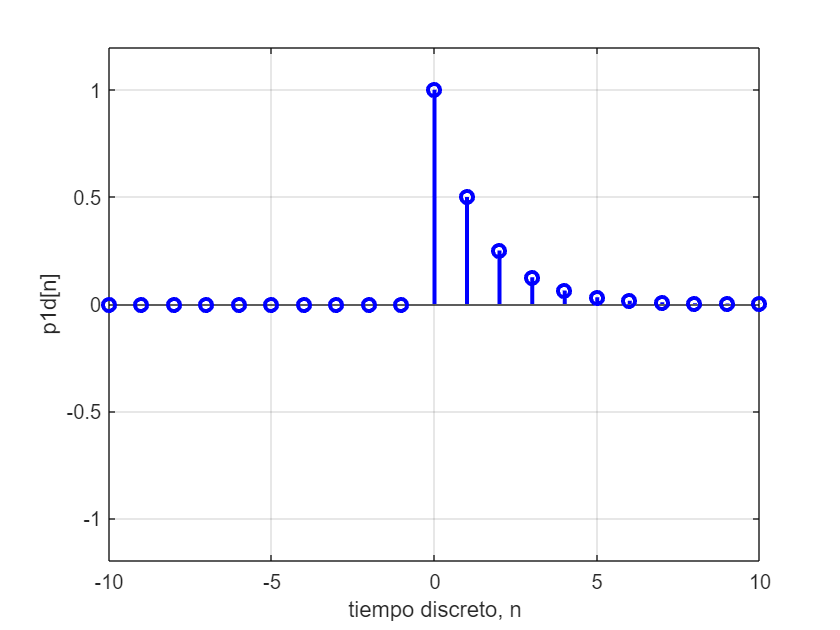

% Señal tipo exponencial
a=1/2;
p1d=(a.^n).*escalon(n);
figure;
stem(n,p1d,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel(['p1d[n]']);
axis([-10 10 -1.2 1.2]);
grid

### 1.2. Escalado y Desplazamiento en Amplitud

Partiendo del script anterior, crear un nuevo script llamado ShiftScaleAmp en el que se representen las señales que se indican a continuación, y que corresponden a desplazamientos y escalados de amplitud de las señales básicas.

- e1[n] = −escalon[n]

- e2[n] = 2 · escalon[n] − 1

- p1[n] = −2 · pulsow[n; 3] + 1

- p2[n] = 2 · delta[n] − 2

(a) Ejecuta el script ShiftScaleAmp y verifica que las representaciones gráficas obtenidas se corresponden con lo esperado.

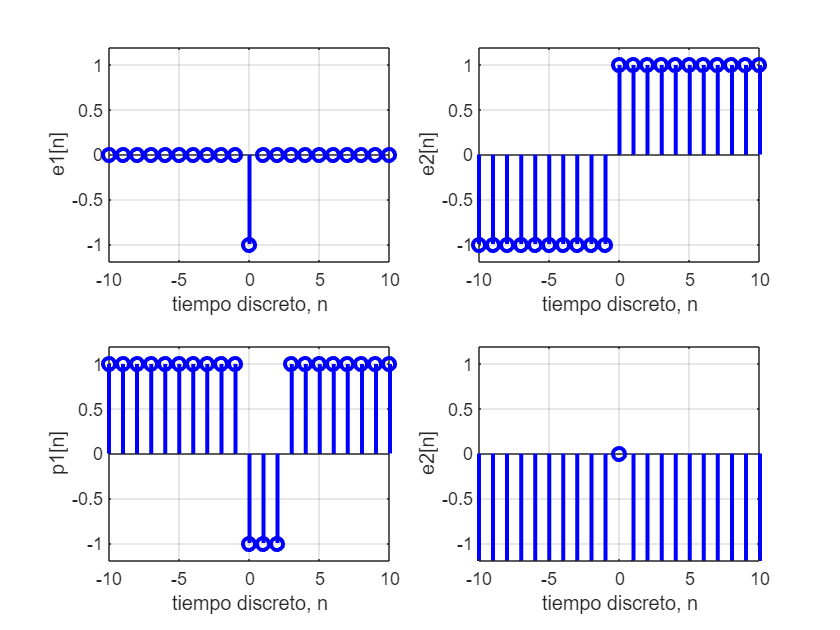

figure
subplot(2,2,1);
e1=-delta(n);
stem(n,e1,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel('e1[n]');
axis([-10 10 -1.2 1.2]);
grid;

subplot(2, 2, 2);
e2=2*escalon(n)-1;
stem(n,e2,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel(['e2[n]']);
axis([-10 10 -1.2 1.2]);
grid

subplot(2, 2, 3);
p1=-2*pulsow(n,3)+1;
stem(n,p1,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel(['p1[n]']);
axis([-10 10 -1.2 1.2]);
grid

subplot(2, 2, 4);
p2=2*delta(n)-2;
stem(n,p2,'b','linewidth',2);
xlabel('tiempo discreto, n'); 
ylabel(['e2[n]']);
axis([-10 10 -1.2 1.2]);
grid

(b) Rellena los huecos que aparecen en el script ap12 incluido a continuación, para que las señales resultantes coincidan con las que se representan en la Figura 1 (ver siguiente página). Emplear combinaciones de señales tipo delta, escalón, pulso, seno y constantes, sin utilizar desplazamiento temporal.

(c) Crea el script ap12 y verifica que las representaciones gráficas obtenidas se corresponden con lo esperado.

%ap12 Representación gráfica de señales en tiempo discreto

% Inicio de figuras y memoria
close all;clear ;
% Eje de tiempos discreto
n=-10:10;

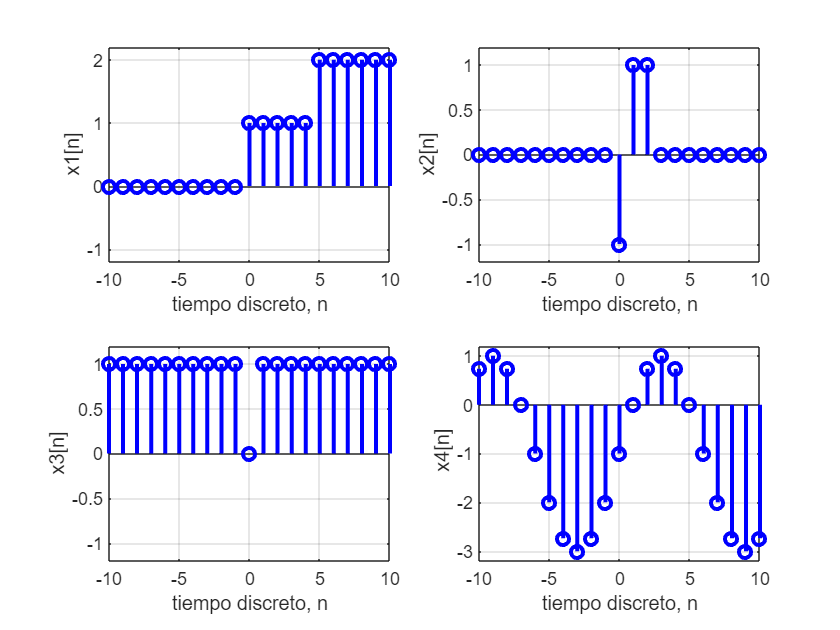


% Ejemplo de combinación de señales tipo escalón y pulso
x1=2*escalon(n)-pulsow(n,5);
subplot(221);stem(n,x1,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x1[n] ');axis([-10 10 -1.2 2.2]);grid

% Ejemplo de combinación de señales tipo pulso y delta
x2=-2*delta(n)+pulsow(n,3);
subplot(222);stem(n,x2,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x2[n] ');axis([-10 10 -1.2 1.2]);grid

% Ejemplo de combinación de constantes con señales básicas
x3=1-delta(n);
subplot(223);stem(n,x3,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x3[n] ');axis([-10 10 -1.2 1.2]);grid

% Ejemplo de combinación de señal sinusoidal discreta
A=2;
B=-1;
x4=A*sin(pi*n/6)+B;
subplot(224);stem(n,x4,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x4[n]');axis([-10 10 -3.2 1.2]);grid

### 1.3. Escalado y Desplazamiento en el Tiempo.

Partiendo de los script anteriores, crear un nuevo script llamado ShiftScaleAxis en el que se representen las señales que se indican a continuación, y que corresponden a desplazamientos y escalados del eje temporal de las señales básicas.

- d1[n] = delta[n + 2]

- d2[n] = delta[n − 2)]

- e1[n] = escalon[−n − 1]

- e2[n] = escalon[−(n − 1)]

- p1[n] = pulsow[2 � n + 3; 8]

- p2[n] = pulsow[−2 � (n + 1); 6]

1. Ejecuta el script ShiftScaleAxis y verifica que las representaciones gráficas obtenidas se corresponden con lo predicho por la teoría, a partir de las definiciones de las señales básicas.

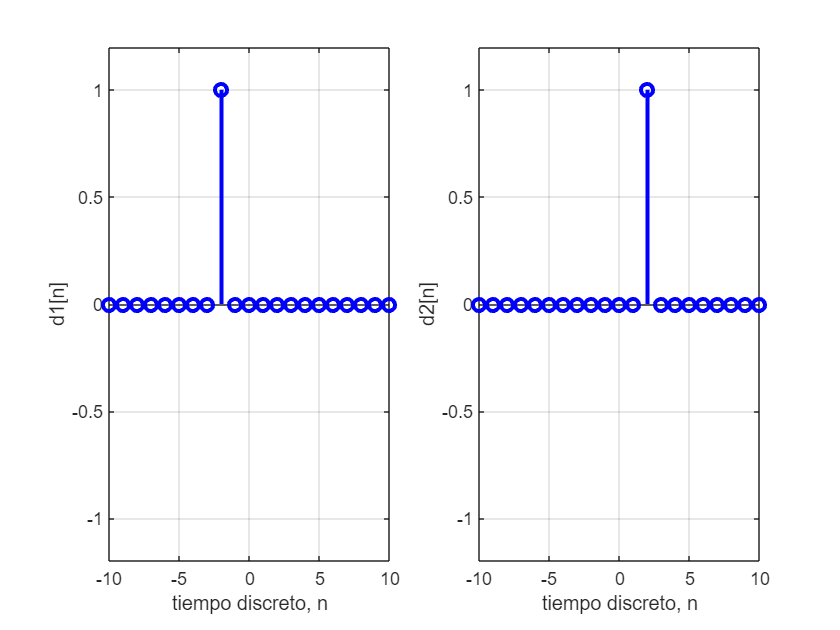

%ap12 Representación gráfica de señales en tiempo discreto

% Inicio de figuras y memoria
close all;clear ;
% Eje de tiempos discreto
n=-10:10;

figure
% Ejemplo de combinación de señales tipo escalón y pulso
d1=delta(n+2);
subplot(121);stem(n,d1,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' d1[n] ');axis([-10 10 -1.2 1.2]);grid

% Ejemplo de combinación de señales tipo pulso y delta
d2=delta(n-2);
subplot(122);stem(n,d2,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' d2[n] ');axis([-10 10 -1.2 1.2]);grid

figure
% Pulsos desplazados a la izquierda (+2) y a la derecha (-2)
d1=delta(n+2);
subplot(121);stem(n,d1,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' d1[n] ');axis([-10 10 -1.2 1.2]);grid

d2=delta(n-2);
subplot(122);stem(n,d2,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' d2[n] ');axis([-10 10 -1.2 1.2]);grid

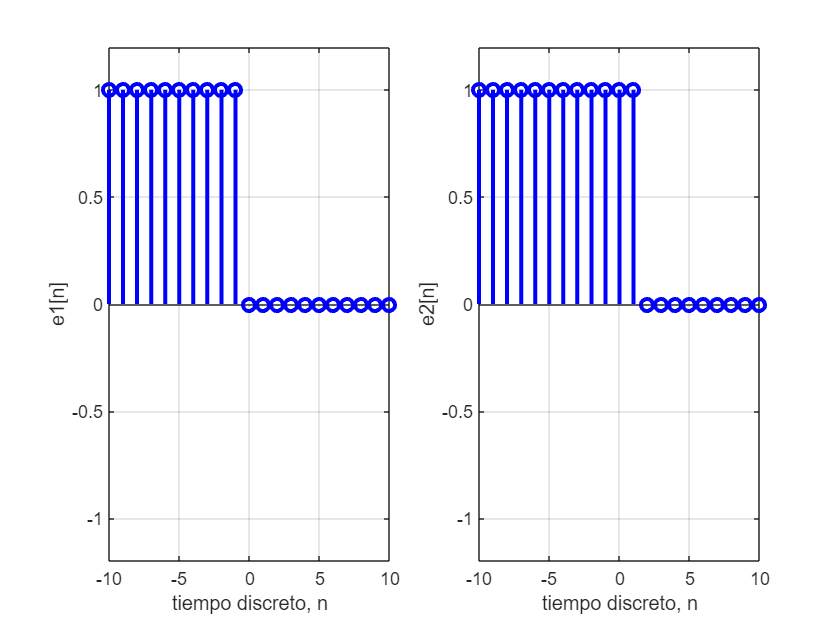

% Escalones simétricos (-n) desplazados a la derecha (-n-1) y a la
% izquierda (-n+1)
e1=escalon(-n-1);
subplot(121);stem(n,e1,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' e1[n] ');axis([-10 10 -1.2 1.2]);grid

e2=escalon(-n+1);
subplot(122);stem(n,e2,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' e2[n] ');axis([-10 10 -1.2 1.2]);grid

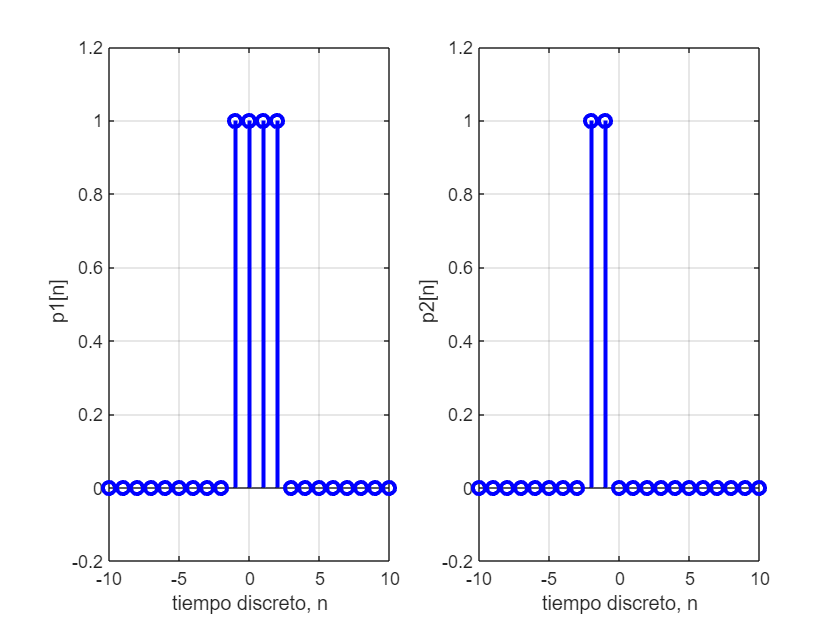

% compresión (2*n), simetría en p2 (-2*(n+1) y desplazamiento de -6 (2*3 en
% p1) y 2*1 en p2
p1=pulsow(2*n+3,8);
p2=pulsow(-2*(n+1), 3);

figure
subplot(121);stem(n,p1,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' p1[n]');axis([-10 10 -0.2 1.2]);grid

subplot(122);stem(n,p2,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' p2[n]');axis([-10 10 -0.2 1.2]);grid

2. Rellena los huecos que aparecen en el script ap13 incluido a continuación, para que las señales resultantes coincidan con las que se representan en la Figura 2 (ver siguiente página). Emplear en cada caso combinaciones del tipo de señal básico indicado con la amplitud necesaria, utilizando además las propiedades de desplazamiento y/o escalado temporal.

3. Crea el script ap13 y verifica que las representaciones gráficas obtenidas se corresponden con lo esperado.

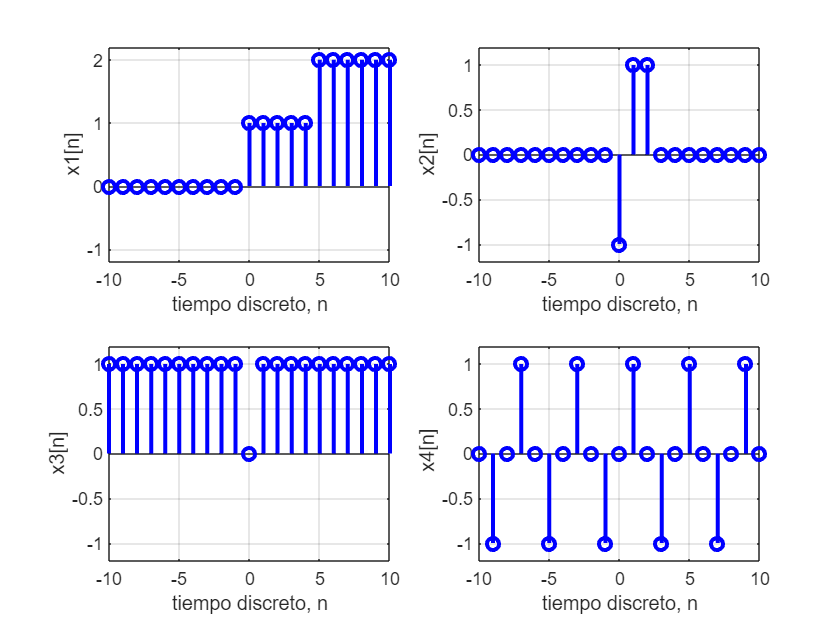

%ap13 Representación gráfica de señales en tiempo discreto
% Inicio de figuras y memoria
close all;clear ;

% Eje de tiempos discreto
n=-10:10;

% Combinación de señales tipo pulso usando desplazamiento temporal
x1=escalon(n)+escalon(n-5);
subplot(221);stem(n,x1,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x1[n] ');axis([-10 10 -1.2 2.2]);grid

% Combinación de señales tipo delta usando desplazamiento temporal
x2=-delta(n)+delta(n-1)+delta(n-2);
subplot(222);stem(n,x2,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x2[n] ');axis([-10 10 -1.2 1.2]);grid

% Combinación de señales tipo escalon usando desplazamiento y escalado temporal
x3=1-delta(n);
subplot(223);stem(n,x3,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x3[n] ');axis([-10 10 -1.2 1.2]);grid
% Combinación de señal sinusoidal discreta
A=1;
B=0;
x4=A*sin(pi*n/2+B);
subplot(224);stem(n,x4,'b','linewidth',2);xlabel('tiempo discreto, n');
ylabel(' x4[n]');axis([-10 10 -1.2 1.2]);grid